# RunTest Example for Data-Driven Dual-level Neural Network Tool for Dynamical System Modeling and Abstraction (D3NN)

clear
close all
clc


## Initialization and Load Data

% Given the trajectories 
SystemOrder=1;
Maximum_Dimension=2;
SystemStateDimension=2;
tol = 0.2;
maximum_entropy=60;
NeuronNum_switch=10;
NeuronNum_single=100;
TF='ReLu';
timetic=3;
e=1.5e-5; % Expected Merged Tolerence
VerificationNum=20;
VerificationDuration=1000;
TrainingStateDimension=1;
InitialBound=[-46 -44;-3.1 -2];
VerificationU_input=[];
% Abstraction
AbstractionNum=400;
AbstractionDuration=200;
AbstractionTol=0.5;
AbstractionEntropy=80;
% Decrease Self LoopNum
SelfLoopNum=100;
Mode = 'Select Dimension';
idx = 2 ;
Name='Angle';
SimulationInputMode='None';
InitialSimulationBound='';

Ini = initialize(SystemOrder,Maximum_Dimension,SystemStateDimension,tol,maximum_entropy,NeuronNum_switch,NeuronNum_single,TF,timetic,e,VerificationNum,VerificationDuration,TrainingStateDimension, InitialBound,VerificationU_input,AbstractionNum,AbstractionDuration,AbstractionTol,AbstractionEntropy,SelfLoopNum,Mode,idx,Name);


## Load Data

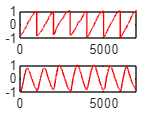

load('DataSet/LASA Data Set/Angle','demos','dt');
for i = 1:size(demos,2)
    TrajData{i} = demos{i}.pos;
end

[xsn,xsnu,tn,input_ps,output_ps,coeff,mu]=Ini.initializingdata(TrajData);
Ini=updateInitial(Ini,coeff,mu,input_ps,output_ps);
figure
for i = 1:size(xsn,1)
    subplot(size(xsn,1),1,i)
    plot(1:size(xsn,2),xsn(i,:),'r')
    hold on
end

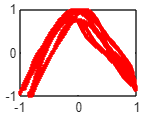


if size(xsn,1)==2
figure
plot(xsn(1,:),xsn(2,:),'.r')
end

## Neural Hybrid System Learning

NHS1=NHS(xsn,tn,Ini);

Starting Maximum Entropy Partitioning with epsilon=60
Number of Partitions 1
历时 0.047641 秒。
Number of Partitions 2
历时 0.033000 秒。
Number of Partitions 3
历时 0.024950 秒。
Number of Partitions 4
历时 0.014733 秒。
Number of Partitions 4
历时 0.019547 秒。
Number of Partitions 4
历时 0.017292 秒。
Number of Partitions 5
历时 0.014343 秒。
Number of Partitions 6
历时 0.013136 秒。
Number of Partitions 7
历时 0.012072 秒。
Number of Partitions 7
历时 0.012181 秒。
Number of Partitions 8
历时 0.011753 秒。
Number of Partitions 8
历时 0.000221 秒。
Number of Partitions 8
历时 0.018410 秒。
Number of Partitions 9
历时 0.016328 秒。
Number of Partitions 10
历时 0.013716 秒。
Number of Partitions 11
历时 0.011124 秒。
Number of Partitions 11
历时 0.014238 秒。
Number of Partitions 11
历时 0.012439 秒。
Number of Partitions 12
历时 0.000087 秒。
Number of Partitions 12
历时 0.016201 秒。
Number of Partitions 13
历时 0.015343 秒。
Number of Partitions 13
历时 0.015182 秒。
Number of Partitions 14
历时 0.013045 秒。
Number of Partitions 14
历时 0.013678 秒。
Number of Partitions 14


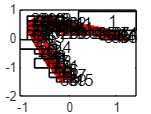

SamplesnPartitionsPlot(NHS1,xsn)

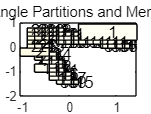

PoltDataPartition(NHS1)

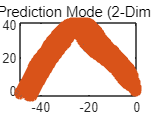

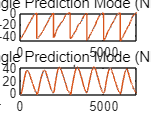

PredictionPlot(NHS1,xsn,tn)

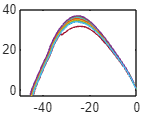

[RandomInput,SimulationTraj]=Runsimulation(NHS1); 

clear xsn tn Ini AbstractionDuration AbstractionEntropy AbstractionNum AbstractionTol coeff idx e i output_ps input_ps

## Transition System Abstration

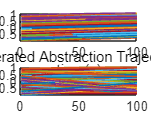

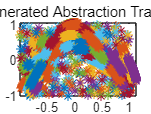

Starting Maximum Entropy Partitioning with epsilon=120
Number of Partitions 1
历时 0.063941 秒。
Number of Partitions 2
历时 0.039688 秒。
Number of Partitions 2
历时 0.039560 秒。
Number of Partitions 3
历时 0.031347 秒。
Number of Partitions 4
历时 0.000015 秒。
Number of Partitions 4
历时 0.047595 秒。
Number of Partitions 5
历时 0.041162 秒。
Number of Partitions 6
历时 0.036468 秒。
Number of Partitions 7
历时 0.000020 秒。
Number of Partitions 7
历时 0.035021 秒。
Number of Partitions 8
历时 0.000016 秒。
Number of Partitions 8
历时 0.000009 秒。
Number of Partitions 8
历时 0.035049 秒。
Number of Partitions 9
历时 0.032738 秒。
Number of Partitions 10
历时 0.000015 秒。
Number of Partitions 10
历时 0.031491 秒。
Number of Partitions 11
历时 0.000020 秒。
Number of Partitions 11
历时 0.000005 秒。
Number of Partitions 11
历时 0.000004 秒。
Number of Partitions 11
历时 0.028327 秒。
Number of Partitions 11
历时 0.000015 秒。
Number of Partitions 11
历时 0.000049 秒。


% Abstraction Adjustment
NHS1.Initialize.abstractionnum=400;
NHS1.Initialize.abstractionduration=100;
NHS1.Initialize.abstractiontol=0.7;
NHS1.Initialize.abstractionentropy=120;

NTS1=NTS(NHS1);

fprintf(['The number of the abstraction cell is ',num2str(size(NTS1.P.intervals,2)),'\n'])

The number of the abstraction cell is 11


MOSEK Version 10.0.46 (Build date: 2023-5-23 19:41:05)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

历时 2.654819 秒。
历时 1.068346 秒。
历时 0.199789 秒。
历时 0.529859 秒。
历时 0.716579 秒。
历时 0.599547 秒。
历时 0.773083 秒。
历时 0.511899 秒。
历时 0.337628 秒。
历时 0.717331 秒。
历时 0.575608 秒。
历时 0.118827 秒。
历时 1.397415 秒。
历时 0.315312 秒。
历时 0.979538 秒。
历时 1.236129 秒。
历时 0.999226 秒。
历时 1.283603 秒。
历时 0.858192 秒。
历时 0.539902 秒。
历时 1.179366 秒。
历时 0.948629 秒。
历时 0.155076 秒。
历时 1.819305 秒。
历时 0.405960 秒。
历时 1.060105 秒。
历时 1.467727 秒。
历时 1.153870 秒。
历时 1.535630 秒。
历时 1.009070 秒。
历时 0.634730 秒。
历时 1.422997 秒。
历时 1.142514 秒。
历时 0.171390 秒。
历时 2.117978 秒。
历时 0.492049 秒。
历时 1.321870 秒。
历时 1.865770 秒。
历时 1.508746 秒。
历时 1.993899 秒。
历时 1.343026 秒。
历时 0.831349 秒。
历时 1.842693 秒。
历时 1.509318 秒。
历时 0.419955 秒。
历时 5.252385 秒。
历时 1.226311 秒。
历时 3.251160 秒。
历时 4.460468 秒。
历时 3.657908 秒。
历时 4.964263 秒。
历时 3.529155 秒。
历时 2.362359 秒。
历时 5.539781 秒。
历时 4.559582 秒。
历时 0.270136 秒。
历时 3.939484 秒。
历时 1.005391 秒。
历

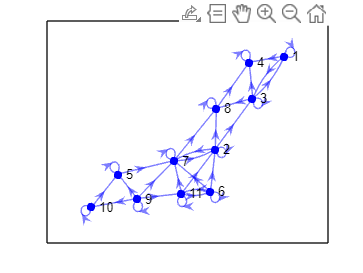

NTS1=TransitionCompute(NTS1);

NTS1=ReduceSelfloop(NTS1);

NTS1=CTLFormulaeInput(NTS1);


CTL Syntax:
Cells should be given in form of P1.id(x-1), eg.
   A[]: Always, A[] P1.id1, always in cell 2, when given initial condition
   E<>: Eventually, E<> (P1.id3 or P1.id6) denotes there should exist at least one path, such that there is one time step in cell 4 or cell 7
   A<>: For all paths, Eventually 
   E[]: Exists, Always, E[] P1.id1 means at leat exist one trace such that its always in cell 2
   leadsto: leads to A[] (P1.id0 leadsto P1.id3) denotes for all trace cell 1 leadsto cell 4 always true.




GenerateSystem(NTS1);
